# Sistemas de Control - EX1

% Periodo de muestreo del sistema
T_mu = 4.5 

T_mu = 4.5000

% Obtener los valores medidos
m_p = get(out, "m_p");
To = get(out, "To");
tout = get(out, "tout");
tout = tout(5:end);

figure(1)
plot(tout, m_p)
title('Flujo de masa de aire')
xlabel('Tiempo (s)')
ylabel('Flujo de masa (kg/s)')

figure(2)
plot(tout, To)
title('Temperatura del aire a la salida')
xlabel('Tiempo (s)')
ylabel('Temperatura (°C)')

## Para systemIdentification

m_p_r = 0.02; % Punto de operación
To_r = 58.83;

% Considerando desde el punto de operación
m_p_i = m_p(80:end) - m_p_r;
To_i = To(80:end) - To_r;

% Obtenidos con systemIdentification
G = tf(p2z0)


G =
 
  From input "u1" to output "y1":
           -3.487
  -------------------------
  s^2 + 0.1207 s + 0.004541
 
Name: p2z0
Continuous-time transfer function.
Model Properties


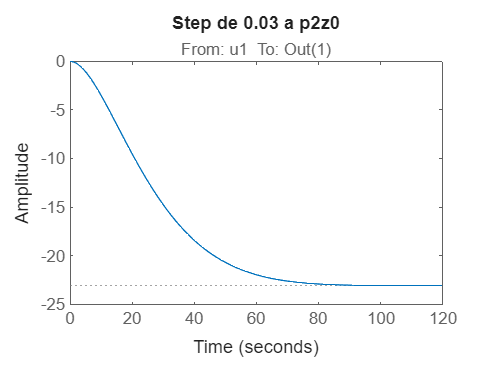

step(0.03*G)
title('Step de 0.03 a p2z0')

### Diseño del controlador

Tes = 100 

Tes = 100

Mp = 0.05

Mp = 0.0500


% Polos y ceros
sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -0.0400 + 0.0419i

s2 = -sigma-wd*1j

s2 = -0.0400 - 0.0419i


so = -2*sigma

so = -0.0800

### PD

% Td = -1/(2*so)

Td = 3.1250

% Gc_p = tf([Td 1], [1])


Gc_p =
 
  3.125 s + 1
 
Continuous-time transfer function.
Model Properties


% Gol = Gc_p*G


Gol =
 
  From input "u1" to output:
       -10.9 s - 3.487
  -------------------------
  s^2 + 0.1207 s + 0.004541
 
Continuous-time transfer function.
Model Properties


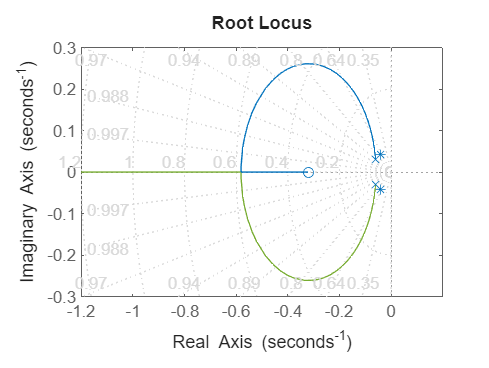

% figure(3)
% rlocus(-Gol)
% grid on
% hold on 
% plot([-sigma  -sigma],[wd  -wd],'*')
% % axis([-0.5 0.2 -0.1  0.1])
% hold off

% Kp = -0.00978 % PD

Kp = -0.0098

% %En lazo cerrado
% Glc = feedback(Kp*Gol,1)


Glc =
 
  From input "u1" to output:
     0.1066 s + 0.0341
  ------------------------
  s^2 + 0.2273 s + 0.03865
 
Continuous-time transfer function.
Model Properties


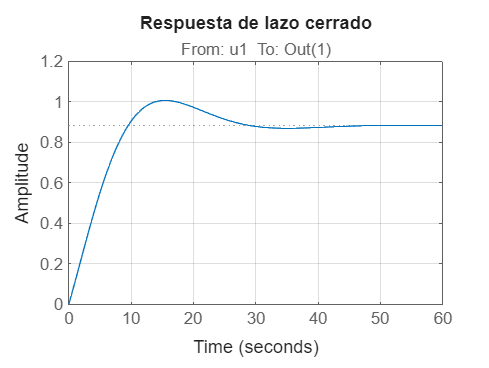

% 
% figure(2)
% step(Glc);
% title('Respuesta de lazo cerrado')
% grid on

% T_PD = 3

T_PD = 3

### PI

sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -0.0400 + 0.0419i

s2 = -sigma-wd*1j

s2 = -0.0400 - 0.0419i


so = -2*sigma

so = -0.0800


Ti = -1/so

Ti = 12.5000

Gc_p = tf([1 1/Ti], [1 0])


Gc_p =
 
  s + 0.08
  --------
     s
 
Continuous-time transfer function.
Model Properties


Gol = Gc_p*G


Gol =
 
  From input "u1" to output:
        -3.487 s - 0.279
  -----------------------------
  s^3 + 0.1207 s^2 + 0.004541 s
 
Continuous-time transfer function.
Model Properties


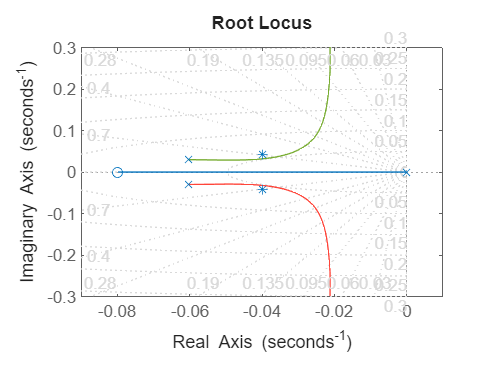

figure(3)
rlocus(-Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
% axis([-0.5 0.2 -0.1  0.1])
hold off

Kp = -0.00032 % PI

Kp = -3.2000e-04


Glc =
 
  From input "u1" to output:
    0.02092 s + 0.006695
  ------------------------
  s^2 + 0.1416 s + 0.01124
 
Continuous-time transfer function.
Model Properties


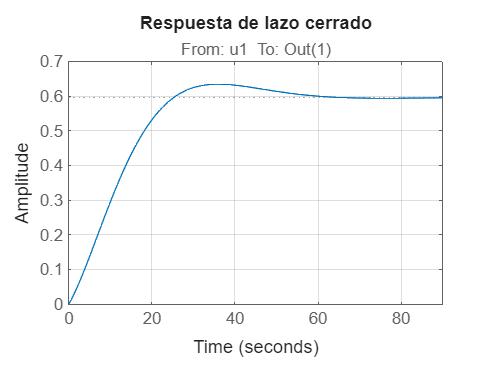

T_r = 54.9 - 7.27

T_r = 47.6300

T_c = 3

T_c = 3

# Servosistema

## Espacio de estados

clear all;
close all;
A = [0 1 0; 0 0 1; -0.002795 -0.06843 -0.3645]

A =          0    1.0000         0
         0         0    1.0000
   -0.0028   -0.0684   -0.3645



B = [0
     0
     1]

B =      0
     0
     1


C = [-2.149 7.715 0]

C =    -2.1490    7.7150         0



Tes = 120 

Tes = 120

Mp = 0.1

Mp = 0.1000


% Factor de amortiguamiento relativo
far = -log(Mp)/sqrt(pi^2 + log(Mp)^2)

far = 0.5912


sigma = 4/Tes

sigma = 0.0333

wn = sigma/far

wn = 0.0564

fi = acos(far)

fi = 0.9383

% Tiempo de subida
Tr = exp(fi/tan(fi))/wn

Tr = 35.2773


% Tr = 29.4 

T = 3.5; % Aprox. Tr/10 

% Muestreo del sistema
FI = eye(3)*T + A*T^2/2 + A^2*T^3/6 + A^3*T^4/24

FI =     2.9906    4.2690    3.2698
   -0.0091    2.7668    3.0772
   -0.0086   -0.2197    1.6452


G = eye(3) + A*FI

G =     0.9909    2.7668    3.0772
   -0.0086    0.7803    1.6452
   -0.0046   -0.1212    0.1806


H = FI*B

H =     3.2698
    3.0772
    1.6452


### Servosistema

% Servosistema agregando integrador
GN = [G zeros(3, 1)
    -C*G 1]

GN =     0.9909    2.7668    3.0772         0
   -0.0086    0.7803    1.6452         0
   -0.0046   -0.1212    0.1806         0
    2.1957   -0.0740   -6.0796    1.0000


HN = [H
    -C*H]

HN =     3.2698
    3.0772
    1.6452
  -16.7138


% Controlabilidad
CoN = [HN GN*HN GN^2*HN GN^3*HN]

CoN =     3.2698   16.8165   30.4377   38.1300
    3.0772    5.0796    3.6696    1.4347
    1.6452   -0.0908   -0.7093   -0.7127
  -16.7138  -19.7640   17.3360   88.2089


det_CoN = det(CoN)

det_CoN = -4.5573e+03

% Dinámica deseada
wd = -pi*sigma/log(Mp)

wd = 0.0455

s1 = -sigma + wd*1i

s1 = -0.0333 + 0.0455i

s2 = -sigma - wd*1i

s2 = -0.0333 - 0.0455i

s3 = -5*sigma

s3 = -0.1667

s4 = -10*sigma % más alejado

s4 = -0.3333


% Polos discretos
z1 = exp(T*s1)

z1 = 0.8964 + 0.1231i

z2 = exp(T*s2)

z2 = 0.8964 - 0.1231i

z3 = exp(T*s3)

z3 = 0.6065

z4 = exp(T*s4)

z4 = 0.3679


% Diseño
KN = acker(GN, HN, [z1 z2 z3 z4])

KN =     0.0018    0.0066    0.0982    0.0002


K2 = KN(1:3)

K2 =     0.0018    0.0066    0.0982


K1 = -KN(4)

K1 = -1.9110e-04

### Observador

% Observabilidad
Ob = [C
      C*G
      C*G^2]

Ob =    -2.1490    7.7150         0
   -2.1957    0.0740    6.0796
   -2.2042   -6.7541   -5.5367


detOb = det(Ob) % detOb = -284.54 != 0 -> Observable

detOb = -284.5418


% Polos del observador
so1 = 2*s1;
so2 = 2*s2;
so3 = 2*s3;

zo1 = exp(T*so1)

zo1 = 0.7884 + 0.2206i

zo2 = exp(T*so2)

zo2 = 0.7884 - 0.2206i

zo3 = exp(T*so3)

zo3 = 0.3679


% Obs en tiempo discreto
Ke = acker(G', C', [zo1 zo2 zo3])'

Ke =     0.0173
    0.0057
   -0.0047
